# Лабораторная работа №3

## **Шумы и фильтрация изображения**

**Наложение шумов**

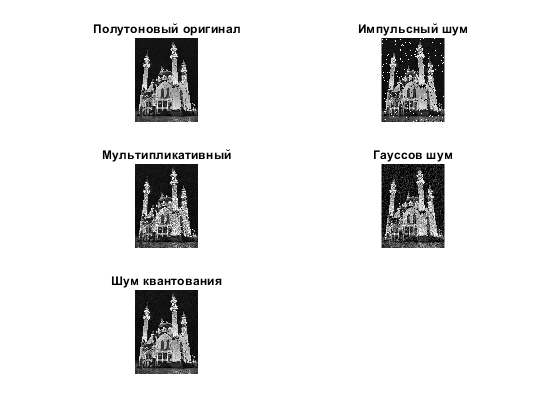

clc
clear all

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);

I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

figure
subplot(3,2,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,2,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,2,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,2,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,2,5)
imshow(I_poisson)
title('Шум квантования')

**Низкочастотная фильтрация шума типа "соль"-"перец"**

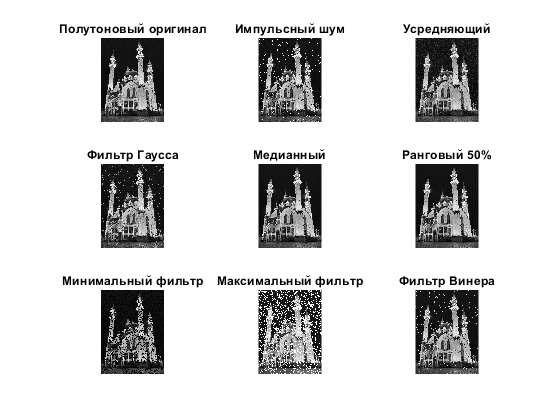


I_f_mean = filter2(fspecial('average',3),I_imp_noise); % усредняющий
I_f_gauss = imgaussfilt(I_imp_noise); % Гауссов
I_f_median = medfilt2(I_imp_noise); % медианная
I_f_median_2 = ordfilt2(I_imp_noise, 5, ones(3,3)); % ранговый (обобщение медианного)
I_f_min = ordfilt2(I_imp_noise, 1, ones(3,3)); % минимальный
I_f_max = ordfilt2(I_imp_noise, 9, ones(3,3)); % максимальный
I_f_wiener = wiener2(I_imp_noise); % Винеровская фильтрация


figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_f_mean / 255)
title('Усредняющий')

subplot(3,3,4)
imshow(I_f_gauss)
title('Фильтр Гаусса')

subplot(3,3,5)
imshow(I_f_median)
title('Медианный')

subplot(3,3,6)
imshow(I_f_median_2)
title('Ранговый 50%')

subplot(3,3,7)
imshow(I_f_min)
title('Минимальный фильтр')

subplot(3,3,8)
imshow(I_f_max)
title('Максимальный фильтр')

subplot(3,3,9)
imshow(I_f_wiener)
title('Фильтр Винера')

**Низкочастотная фильтрация мультипликативного шума**

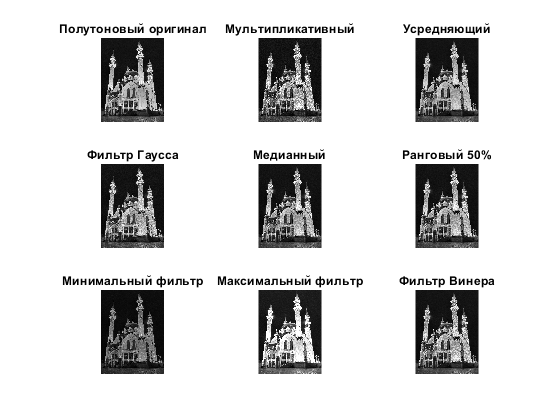

I_f_mean = filter2(fspecial('average',3),I_speckle); % усредняющий
I_f_gauss = imgaussfilt(I_speckle); % Гауссов
I_f_median = medfilt2(I_speckle); % медианная
I_f_median_2 = ordfilt2(I_speckle, 5, ones(3,3)); % ранговый (обобщение медианного)
I_f_min = ordfilt2(I_speckle, 1, ones(3,3)); % минимальный
I_f_max = ordfilt2(I_speckle, 9, ones(3,3)); % максимальный
I_f_wiener = wiener2(I_speckle); % Винеровская фильтрация

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,3)
imshow(I_f_mean / 255)
title('Усредняющий')

subplot(3,3,4)
imshow(I_f_gauss)
title('Фильтр Гаусса')

subplot(3,3,5)
imshow(I_f_median)
title('Медианный')

subplot(3,3,6)
imshow(I_f_median_2)
title('Ранговый 50%')

subplot(3,3,7)
imshow(I_f_min)
title('Минимальный фильтр')

subplot(3,3,8)
imshow(I_f_max)
title('Максимальный фильтр')

subplot(3,3,9)
imshow(I_f_wiener)
title('Фильтр Винера')

**Низкочастотная фильтрация Гауссова шума**

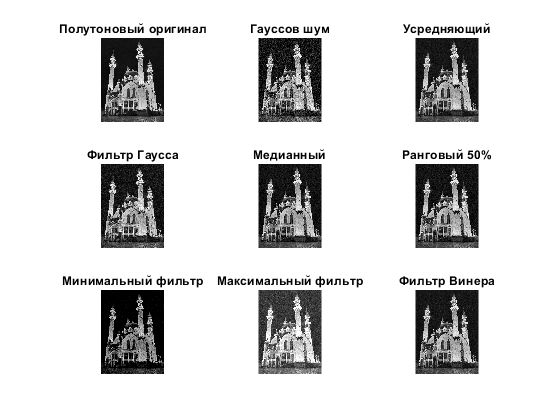

I_f_mean = filter2(fspecial('average',3),I_gauss); % усредняющий
I_f_gauss = imgaussfilt(I_gauss); % Гауссов
I_f_median = medfilt2(I_gauss); % медианная
I_f_median_2 = ordfilt2(I_gauss, 5, ones(3,3)); % ранговый (обобщение медианного)
I_f_min = ordfilt2(I_gauss, 1, ones(3,3)); % минимальный
I_f_max = ordfilt2(I_gauss, 9, ones(3,3)); % максимальный
I_f_wiener = wiener2(I_gauss); % Винеровская фильтрация

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,3)
imshow(I_f_mean / 255)
title('Усредняющий')

subplot(3,3,4)
imshow(I_f_gauss)
title('Фильтр Гаусса')

subplot(3,3,5)
imshow(I_f_median)
title('Медианный')

subplot(3,3,6)
imshow(I_f_median_2)
title('Ранговый 50%')

subplot(3,3,7)
imshow(I_f_min)
title('Минимальный фильтр')

subplot(3,3,8)
imshow(I_f_max)
title('Максимальный фильтр')

subplot(3,3,9)
imshow(I_f_wiener)
title('Фильтр Винера')

**Низкочастотная фильтрация шума квантования**

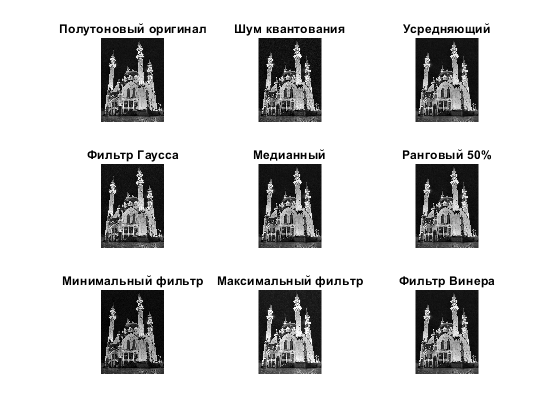

I_f_mean = filter2(fspecial('average',3),I_poisson); % усредняющий
I_f_gauss = imgaussfilt(I_poisson); % Гауссов
I_f_median = medfilt2(I_poisson); % медианная
I_f_median_2 = ordfilt2(I_poisson, 5, ones(3,3)); % ранговый (обобщение медианного)
I_f_min = ordfilt2(I_poisson, 1, ones(3,3)); % минимальный
I_f_max = ordfilt2(I_poisson, 9, ones(3,3)); % максимальный
I_f_wiener = wiener2(I_poisson); % Винеровская фильтрация


figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,3)
imshow(I_f_mean / 255)
title('Усредняющий')

subplot(3,3,4)
imshow(I_f_gauss)
title('Фильтр Гаусса')

subplot(3,3,5)
imshow(I_f_median)
title('Медианный')

subplot(3,3,6)
imshow(I_f_median_2)
title('Ранговый 50%')

subplot(3,3,7)
imshow(I_f_min)
title('Минимальный фильтр')

subplot(3,3,8)
imshow(I_f_max)
title('Максимальный фильтр')

subplot(3,3,9)
imshow(I_f_wiener)
title('Фильтр Винера')

**Высокочастотная фильтрация для оригинального изображения**

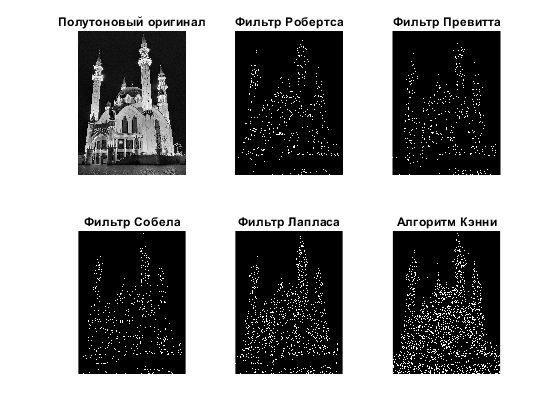

figure;

subplot(2,3,1)
imshow(I)
title('Полутоновый оригинал')

I_roberst = edge(I,'roberts'); % работает с маской 2 х 2, 2 штуки
subplot(2,3,2)
imshow(I_roberst)
title('Фильтр Робертса')

I_prewitt = edge(I,'prewitt'); % 2 ортогональные маски размерами 3 х 3
subplot(2,3,3)
imshow(I_prewitt)
title('Фильтр Превитта')

I_sobel = edge(I,'sobel'); % отличается от Превитта наличием весов
subplot(2,3,4)
imshow(I_sobel)
title('Фильтр Собела')

I_laplas = edge(I,'log'); % использует аппроксимацию вторых производных
subplot(2,3,5)
imshow(I_laplas)
title('Фильтр Лапласа')

I_canny = edge(I,'canny');
subplot(2,3,6)
imshow(I_canny)
title('Алгоритм Кэнни')

**Инвертированный вариант высокочастотной фильтрации**

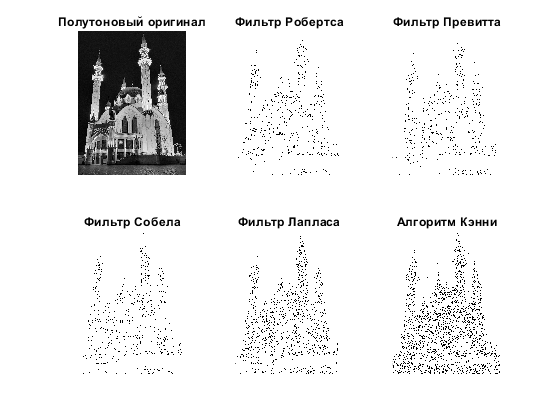

figure;

subplot(2,3,1)
imshow(I)
title('Полутоновый оригинал')

I_roberst = edge(I,'roberts'); % работает с маской 2 х 2, 2 штуки
subplot(2,3,2)
imshow(~I_roberst)
title('Фильтр Робертса')

I_prewitt = edge(I,'prewitt'); % 2 ортогональные маски размерами 3 х 3
subplot(2,3,3)
imshow(~I_prewitt)
title('Фильтр Превитта')

I_sobel = edge(I,'sobel'); % отличается от Превитта наличием весов
subplot(2,3,4)
imshow(~I_sobel)
title('Фильтр Собела')

I_laplas = edge(I,'log'); % использует аппроксимацию вторых производных
subplot(2,3,5)
imshow(~I_laplas)
title('Фильтр Лапласа')

I_canny = edge(I,'canny');
subplot(2,3,6)
imshow(~I_canny)
title('Алгоритм Кэнни')

**Реализация контргармонического усредняющего фильтра с различными значениями параметра Q**

**Q = 1.5**

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);

I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

J_noise = CHMF(I_imp_noise,3,1.5);
J_speckle = CHMF(I_speckle,3,1.5);
J_gaussian = CHMF(I_gauss,3,1.5);
J_poisson = CHMF(I_poisson,3,1.5);

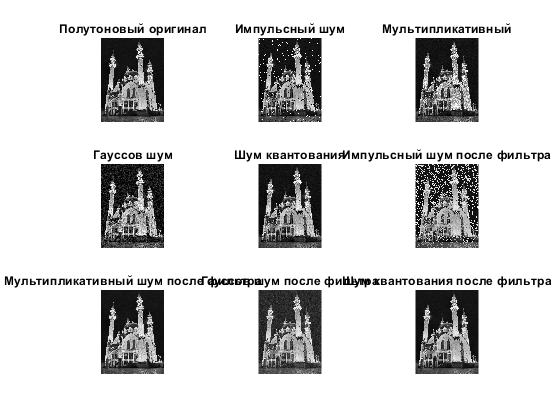

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,5)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,6)
imshow(J_noise)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(J_speckle)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(J_gaussian)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(J_poisson)
title('Шум квантования после фильтра')

**Q = - 0.5**

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);

I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

J_noise = CHMF(I_imp_noise,3,-0.5);
J_speckle = CHMF(I_speckle,3,-0.5);
J_gaussian = CHMF(I_gauss,3,-0.5);
J_poisson = CHMF(I_poisson,3,-0.5);

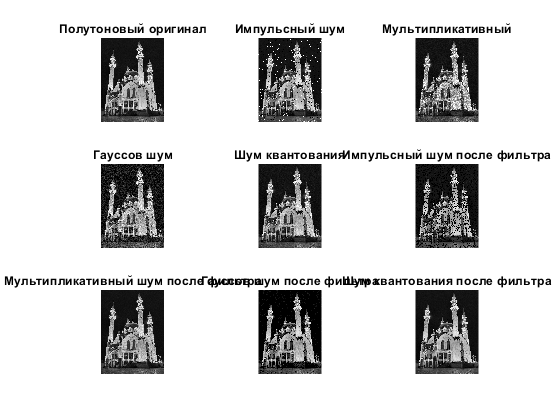

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,5)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,6)
imshow(J_noise)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(J_speckle)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(J_gaussian)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(J_poisson)
title('Шум квантования после фильтра')

**Q = -1 **

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);

I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

J_noise = CHMF(I_imp_noise,3,-1);
J_speckle = CHMF(I_speckle,3,-1);
J_gaussian = CHMF(I_gauss,3,-1);
J_poisson = CHMF(I_poisson,3,-1);

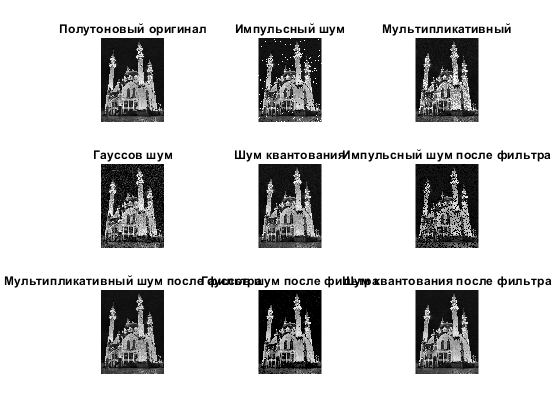

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,5)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,6)
imshow(J_noise)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(J_speckle)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(J_gaussian)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(J_poisson)
title('Шум квантования после фильтра')

**Q = 0**

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);

I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

J_noise = CHMF(I_imp_noise,3,-1);
J_speckle = CHMF(I_speckle,3,-1);
J_gaussian = CHMF(I_gauss,3,-1);
J_poisson = CHMF(I_poisson,3,-1);

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);
I = im2double(I);
I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');
I_f_mean_imp = filter2(fspecial('average',3),I_imp_noise); % усредняющий
I_f_mean_sp = filter2(fspecial('average',3),I_speckle); % усредняющий
I_f_mean_ga = filter2(fspecial('average',3),I_gauss); % усредняющий
I_f_mean_po = filter2(fspecial('average',3),I_poisson); % усредняющий

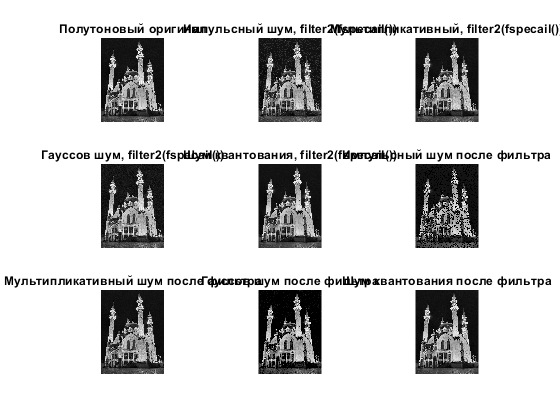

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_f_mean_imp)
title('Импульсный шум, filter2(fspecail())')

subplot(3,3,3)
imshow(I_f_mean_sp)
title('Мультипликативный, filter2(fspecail())')

subplot(3,3,4)
imshow(I_f_mean_ga)
title('Гауссов шум, filter2(fspecail())')

subplot(3,3,5)
imshow(I_f_mean_po)
title('Шум квантования, filter2(fspecail())')

subplot(3,3,6)
imshow(J_noise)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(J_speckle)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(J_gaussian)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(J_poisson)
title('Шум квантования после фильтра')

**Применение адаптивной медианной фильтрации**

I = imread("church.jpg");
I = rgb2gray(I);  % перевод в полутоновое
I = imrotate(I,-90);
I = im2double(I);
I_imp_noise = imnoise(I, 'salt & pepper');
I_speckle = imnoise(I,'speckle');
I_gauss = imnoise(I,"gaussian");
I_poisson = imnoise(I, 'poisson');

output_imp = AMF(I_imp_noise, 11);
output_sp = AMF(I_speckle, 11);
output_ga = AMF(I_gauss, 11);
output_po = AMF(I_poisson, 11);

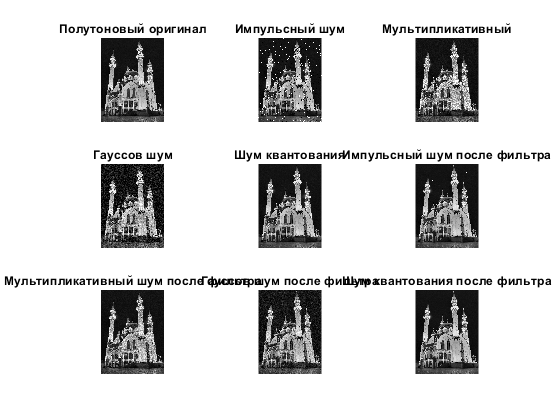

figure

subplot(3,3,1)
imshow(I)
title('Полутоновый оригинал')

subplot(3,3,2)
imshow(I_imp_noise)
title('Импульсный шум')

subplot(3,3,3)
imshow(I_speckle)
title('Мультипликативный')

subplot(3,3,4)
imshow(I_gauss)
title('Гауссов шум')

subplot(3,3,5)
imshow(I_poisson)
title('Шум квантования')

subplot(3,3,6)
imshow(output_imp)
title('Импульсный шум после фильтра')

subplot(3,3,7)
imshow(output_sp)
title('Мультипликативный шум после фильтра')

subplot(3,3,8)
imshow(output_ga)
title('Гауссов шум после фильтра')

subplot(3,3,9)
imshow(output_po)
title('Шум квантования после фильтра')

**Использование адаптивной медианной фильтрации**

function I_rez = AMF(I,s_max)

I = im2double(I);
s = 3; 

[nrows, ncols] = size(I);

I_rez = I;
mask_base = padarray(I,[floor(s_max / 2) floor(s_max / 2)], 'symmetric');

for i = 1 : nrows
    for j = 1 : ncols
        mask = mask_base(i : i + s - 1, j : j + s - 1);
        z_min = min(mask(:));
        z_max = max(mask(:));
        z_med = median(mask(:));
        while s <= s_max
            A1 = z_med - z_min;
            A2 = z_med - z_max;
            if A1 > 0 && A2 < 0  % 1.а == True
                B1 = I(i,j) - z_min;
                B2 = I(i,j) - z_max;
                if B1 > 0 && B2 < 0
                    I_rez(i,j) = I(i,j);
                else
                    I_rez(i,j) = z_med;
                end
                break; 
            else % 1.a == False
                s = s + 2;
                if s <= s_max
                    continue
                else 
                    I_rez(i,j) = I(i,j);
                end
            end
        end
        s = 3; 
        
    end
end

end

**Функция для контргармонического усредняющего фильтра с различными значениями параметра Q**

function J = CHMF(I,m,q) % исходное изображение, размер маски, значение Q
I = im2double(I);
J = zeros(size(I));  % задаём пустой массив размером исходного изображения
mask_base = padarray(I,[floor(m / 2) floor(m / 2)],'symmetric'); % симметричным образом вокруг
% нашего массива добавляем элементы, которые симметричны границе

for i = 1:size(I,1)
    for j = 1:size(I,2)
        mask = mask_base(i : i + (m - 1), j : j + (m - 1)); % подаём в нашу функцию числа
        % от 1 до m, 
        numerator = sum(mask.^(q + 1), 'all'); % считаем числитель
        deno = sum(mask.^(q), 'all'); % знаминатель
        if deno == 0  % если знаминатель 0, то, чтобы избежать деление на 0,
        % берём 0
            J(i,j) = 0;
        else
            J(i,j) = numerator / deno;
        end
    end
end

end